# **Numerical Differentiation **

## Example Problem

Estimate the velocity and acceleration from datasets of position of an object.

clear all

t = 0:0.2:4;
y = [-5.87 -4.23 -2.55 -0.89 0.67 2.09 3.31 4.31 5.06 5.55 5.78 5.77 5.52 5.08 4.46 3.72 2.88 2.00 1.10 0.23 -0.59];

A simple two-point differentiation can be used :

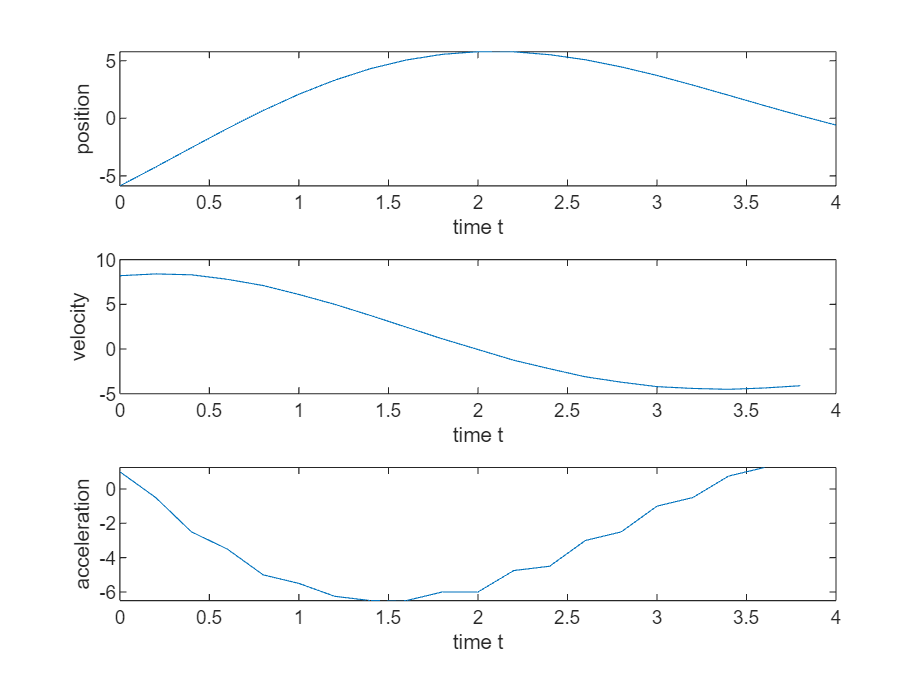

% asusume evenly spaced h
h=0.2;
vel = diff(y)./h;
acc = diff(y,2)./h^2;

%acc = diff(diff(y));
tv=t(1:length(vel));
ta=t(1:length(acc));

figure
subplot (3,1,1)
    plot(t,y)
    xlabel('time t')
    ylabel('position')

subplot (3,1,2)
    plot(tv,vel)
    xlabel('time t')
    ylabel('velocity')

subplot (3,1,3)
    plot(ta,acc)
    xlabel('time t')
    ylabel('acceleration')

## Differentiation Formula

## 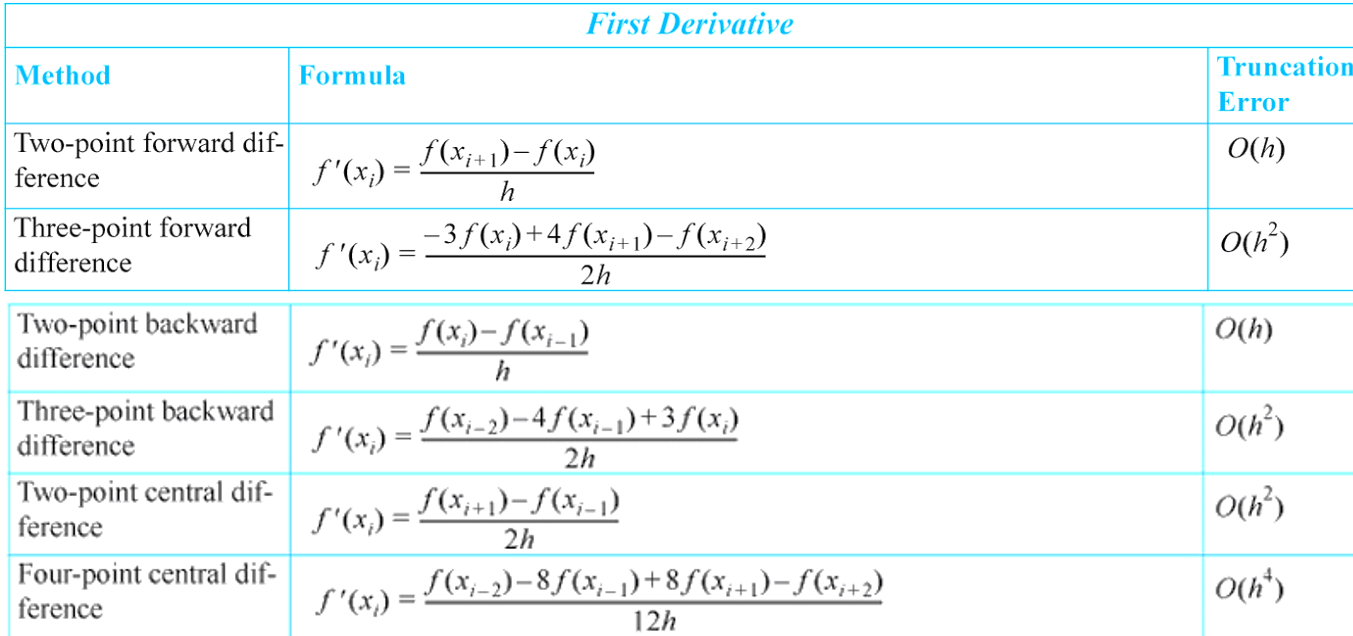

## Exercise

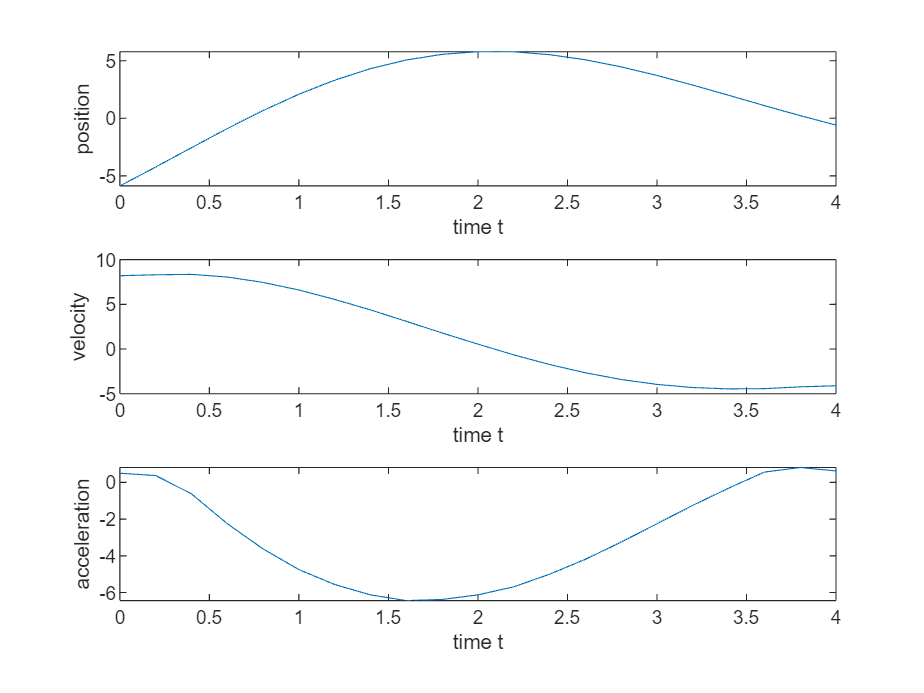

vel = derivative(t,y);
acc = derivative(t,vel);

figure
subplot (3,1,1)
    plot(t,y)
    xlabel('time t')
    ylabel('position')

subplot (3,1,2)
    plot(t,vel)
    xlabel('time t')
    ylabel('velocity')

subplot (3,1,3)
    plot(t,acc)
    xlabel('time t')
    ylabel('acceleration')

## Exercise 1

Create derivative1d(x,y) that returns numerical differentiation  

- Use two-point forward for the first data point

- Use two-central difference 

- Use two-point backward for the last data point

The function `derivative` can be designed simply as

function dydt = derivative(t,y)
% The derivative: using two-point central difference formula
% except the first and the last data points. 

    n = length(t);
    % two-point forward for the first point
    
    dydt(1)=0;
    % [TO-DO Exercise]
    dydt(1)=(y(2)-y(1))/(t(2)-t(1));    
    
    % two-point central difference 
    for i=2:n-1
        dydt(i)=0;
        % [TO-DO Exercise]
        dydt(i)=(y(i+1)-y(i-1))/(t(i+1)-t(i-1));
    end    

    % two-point backward for the last point
    dydt(n)=0;
    % [TO-DO Exercise]
    dydt(n)=(y(n)-y(n-1))/(t(n)-t(n-1));
end

## Exercise 2

Create derivative1d(x,y) that returns numerical differentiation  with O(h^2) error order 

- Use 3-points forward and backwards method for the first and last data point

- Otherwise use 2-points central difference

function dydt = derivative1d(t,y)
% For starting and end points: Use 3-points forward and backwards 
% For other points: Use 2-points central dfference

% [TO-DO Exercise]
% [TO-DO Exercise]

dydt=0 % change  this
end